clc;  clearvars;
%close all;

figure

## 1. Generate data set - original pdf is a Gaussian mixture model.

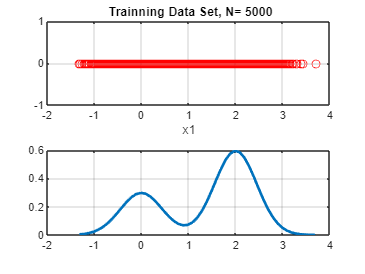

d=1; %dimension
m=[0; 2]'; %means
S(:,:,1)=0.2*eye(d); % Covariance matrix
S(:,:,2)=0.2*eye(d);
P=[1/3 2/3];  %A priori Probabilitys
N=5000;  % Number points of the data set
%N=1000;
randn('seed',0);
%randn('seed',1);
[X]=generate_gauss_classes(m,S,P,N); %generate data trainning

xmin=min(X); xmax=max(X); 

%%Display trainning data set 
subplot(2,1,1); plot(X,0,'o r'); title([' Trainning Data Set, N= ' num2str(N)])
xlabel ('x1'); grid on
%axis([1.2*xmin 1.2*xmax  -1  1]);

% Display the pdf
%xmin=-5;  xmax=5;  %smallest and largets values of x for which the pdf will be estimated.
x=xmin:0.1:xmax;
pdfx=P(1)*(1/sqrt(2*pi*S(:,:,1)))*exp( -(x-m(1)).^2/(2*S(:,:,1))) +P(2)*(1/sqrt(2*pi*S(:,:,2)))*exp(-((x-m(2)).^2)/(2*S(:,:,2)));
subplot(2,1,2);
plot(x,pdfx,'LineWidth',2); grid on

## 2- Use function knn_density_estimate to estimate the pdf para k

Ajuste el valor del número de vecinos k

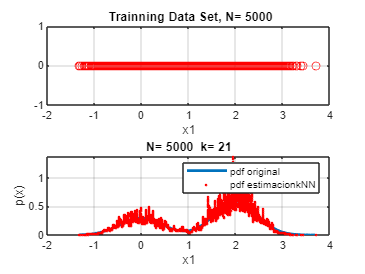

%k=5;
k=21;
%k=50;
%k=100;
%k=150;
%k=200;
%k=300;

hold on;

%pdfx_approx=knn_density_estimate(X,k,xmin,xmax,0.1);
%plot(xmin:0.1:xmax,pdfx_approx,'r','LineWidth',2); title(['N= ' num2str(N) '  k= ' num2str(k) ] )
pdfx_approx=estimar_kNN_density(X,X,k);
plot(X,pdfx_approx,'.r','LineWidth',2); title(['N= ' num2str(N) '  k= ' num2str(k) ] )

xlabel('x1'); ylabel('p(x)')
legend('pdf original','pdf estimacionkNN')

%axis([xmin xmax  -0.1  1.1]); grid on